# FAVAD leakage (EPANET 2.3)

Leakage model demo Note: we can't just sum the leak rates at both end nodes together since in general the nodes can have leakage contributed by other connecting pipes.

clear; close all; clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Input file

INP = 'Net1.inp';
d = epanet(INP);

EPANET version {20303} loaded (EMT version {v2.3.03 - Last Update: 21/01/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



q_unit = d.getFlowUnits();
p_unit = d.getOptionsPressureUnits();
fprintf('[Units] Flow=%s | Pressure=%s\n', q_unit, p_unit);

[Units] Flow=GPM | Pressure=PSI


## Simulation settings

SIM_HOURS    = 24;
HYD_STEP_MIN = 60;

d.setTimeSimulationDuration(SIM_HOURS * 3600);
d.setTimeHydraulicStep(HYD_STEP_MIN * 60);

nLinks = d.getLinkCount();

## Apply leakage to multiple links

{LinkID, LC1, LC2}

leakLinks = { ...
    '21',  1.0,  0.10;
    '12',  0.8,  0.05;
    '31',  0.9,  0.08;
};

fprintf('\n===== APPLY LEAKAGE =====\n');


===== APPLY LEAKAGE =====



leakLinkIds     = leakLinks(:,1);
nLeakLinks      = size(leakLinks,1);
leakLinkIndices = zeros(nLeakLinks,1);

for k = 1:nLeakLinks
    linkID = leakLinks{k,1};
    LC1k   = leakLinks{k,2};
    LC2k   = leakLinks{k,3};

    linkIdx = d.getLinkIndex(linkID);
    if isempty(linkIdx) || linkIdx <= 0
        error('Link ID "%s" not found.', linkID);
    end

    leakLinkIndices(k) = linkIdx;

    d.setLinkLeakArea(linkIdx, LC1k);
    d.setLinkExpansionProperties(linkIdx, LC2k);

    fprintf('Applied leakage to link %s (index %d): LC1=%.6g, LC2=%.6g\n', ...
        linkID, linkIdx, LC1k, LC2k);
end

Applied leakage to link 21 (index 4): LC1=1, LC2=0.1
Applied leakage to link 12 (index 3): LC1=0.8, LC2=0.05
Applied leakage to link 31 (index 6): LC1=0.9, LC2=0.08


## Run hydraulics and retrieve time series

res = d.getComputedHydraulicTimeSeries( ...
    'linkleakagerate', 'nodeleakageflow', 'emitterflow', ...
    'demanddelivered', 'demandrequested', 'time');

time_s = res.Time(:);
time_h = time_s / 3600;

leak_link_ts = res.LinkLeakageRate;   % [time x links] (L/s)
leak_node_ts = res.NodeLeakageFlow;   % [time x nodes] (L/s)

## Core results: totals, averages, peak, volumes

totalLeak_ts_LPS = sum(leak_link_ts, 2, 'omitnan');   % L/s
avgTotalLeak_LPS = mean(totalLeak_ts_LPS, 'omitnan'); % L/s

if numel(time_s) >= 2
    totalLeakedVolume_m3 = trapz(time_s, totalLeak_ts_LPS) / 1000; % (L/s)*s -> L -> m^3
else
    totalLeakedVolume_m3 = NaN;
end

[peakTotalLeak_LPS, idxPeak] = max(totalLeak_ts_LPS);
tPeak_h = time_h(idxPeak);

fprintf('\n===== LEAKAGE SUMMARY =====\n');


===== LEAKAGE SUMMARY =====


fprintf('Average total leakage   : %.3f L/s\n', avgTotalLeak_LPS);

Average total leakage   : 173.032 L/s


fprintf('Peak total leakage      : %.3f L/s at t = %.2f h\n', peakTotalLeak_LPS, tPeak_h);

Peak total leakage      : 183.441 L/s at t = 15.00 h


fprintf('Total leaked volume     : %.2f m3/day (over %d h)\n', totalLeakedVolume_m3, SIM_HOURS);

Total leaked volume     : 14949.81 m3/day (over 24 h)


## Per-link mean leakage and peak snapshot

avgLeak_perLink_LPS = mean(leak_link_ts, 1, 'omitnan')';   % [links x 1]
leak_at_peak_LPS    = leak_link_ts(idxPeak, :)';           % [links x 1]

## Links by mean leakage

topN = 3;

[sortedVals, sortedIx] = sort(avgLeak_perLink_LPS, 'descend');
topN = min(topN, nLinks);

topLinkIndex = sortedIx(1:topN);
topLinkLeak  = sortedVals(1:topN);

topLinkID = strings(topN,1);
for i = 1:topN
    idx = topLinkIndex(i);
    topLinkID(i) = string(d.getLinkNameID(idx));
end

fprintf('\nTop-%d links by MEAN leakage (L/s):\n', topN);


Top-3 links by MEAN leakage (L/s):


Ttop = table(topLinkIndex, topLinkID, topLinkLeak, ...
    'VariableNames', {'LinkIndex','LinkID','MeanLeak_LPS'});
disp(Ttop);

    LinkIndex    LinkID      MeanLeak_LPS  
    _________    ______    ________________

        4         "21"      73.116588299091
        6         "31"     56.8689101292537
        3         "12"     43.0460410484901



## Consistency checks for ALL leaky links (nodes for each link)

fprintf('\n===== CONSISTENCY CHECKS (per leaky link) =====\n');


===== CONSISTENCY CHECKS (per leaky link) =====



tol_L = 0.01;

checkTable = table('Size',[nLeakLinks 7], ...
    'VariableTypes', {'string','double','double','double','double','double','double'}, ...
    'VariableNames', {'LinkID','LinkIndex','Node1','Node2','LeakLink_Total','LeakNodes_Total','AbsDiff'});

for k = 1:nLeakLinks
    linkID  = string(leakLinkIds{k});
    linkIdx = leakLinkIndices(k);

    nodes = d.getLinkNodesIndex(linkIdx);
    node1 = nodes(1);
    node2 = nodes(2);

    leak_nodes_total = sum(leak_node_ts(:, nodes), 'all', 'omitnan');
    leak_link_total  = sum(leak_link_ts(:, linkIdx), 'all', 'omitnan');
    absDiff          = abs(leak_link_total - leak_nodes_total);

    checkTable.LinkID(k)          = linkID;
    checkTable.LinkIndex(k)       = linkIdx;
    checkTable.Node1(k)           = node1;
    checkTable.Node2(k)           = node2;
    checkTable.LeakLink_Total(k)  = leak_link_total;
    checkTable.LeakNodes_Total(k) = leak_nodes_total;
    checkTable.AbsDiff(k)         = absDiff;

    fprintf('Link %s (idx %d) nodes (%d,%d): LinkSum=%.4f | NodeSum=%.4f | Diff=%.4f\n', ...
        linkID, linkIdx, node1, node2, leak_link_total, leak_nodes_total, absDiff);

    assert(absDiff < tol_L, 'Leak mismatch for link %s: link != nodes', linkID);
end

Link 21 (idx 4) nodes (5,6): LinkSum=1901.0313 | NodeSum=1901.0317 | Diff=0.0004
Link 12 (idx 3) nodes (3,4): LinkSum=1119.1971 | NodeSum=1119.1971 | Diff=0.0000
Link 31 (idx 6) nodes (8,9): LinkSum=1478.5917 | NodeSum=1478.5916 | Diff=0.0000



disp(checkTable);

    LinkID    LinkIndex    Node1    Node2     LeakLink_Total     LeakNodes_Total           AbsDiff       
    ______    _________    _____    _____    ________________    ________________    ____________________

     "21"         4          5        6      1901.03129577637    1901.03168106079    0.000385284423828125
     "12"         3          3        4      1119.19706726074    1119.19709205627    2.47955322265625e-05
     "31"         6          8        9       1478.5916633606    1478.59164237976    2.09808349609375e-05



## Plots

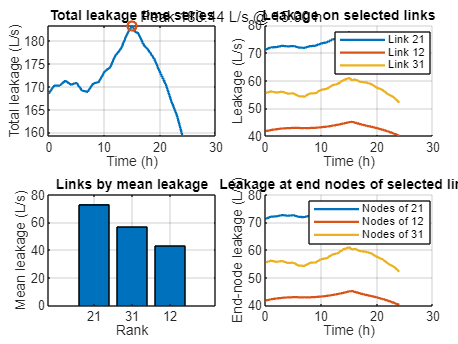

figure('Name','Leakage Results','Color','w');
tiledlayout(2,2,'Padding','compact','TileSpacing','compact');

% 1) Total leakage over time
nexttile;
plot(time_h, totalLeak_ts_LPS, 'LineWidth', 1.5);
grid on;
xlabel('Time (h)');
ylabel('Total leakage (L/s)');
title('Total leakage time series');

hold on;
plot(time_h(idxPeak), peakTotalLeak_LPS, 'o', 'LineWidth', 1.5);
text(time_h(idxPeak), peakTotalLeak_LPS, ...
    sprintf('  Peak %.2f L/s @ %.2f h', peakTotalLeak_LPS, tPeak_h), ...
    'VerticalAlignment','bottom');
hold off;

% 2) Leakage over time for each leaky link
nexttile;
hold on;
for k = 1:nLeakLinks
    linkID  = string(leakLinkIds{k});
    linkIdx = leakLinkIndices(k);
    plot(time_h, leak_link_ts(:, linkIdx), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Link %s', linkID));
end
grid on;
xlabel('Time (h)');
ylabel('Leakage (L/s)');
title('Leakage on selected links');
legend('Location','best');
hold off;

% 3) Links bar (mean leakage)
nexttile;
bar(topLinkLeak);
grid on;
xlabel('Rank');
ylabel('Mean leakage (L/s)');
title('Links by mean leakage');
xticks(1:topN);
xticklabels(string(topLinkID));
xtickangle(0);

% 4) Sum of leakage at end nodes (per leaky link)
nexttile;
hold on;
for k = 1:nLeakLinks
    linkID  = string(leakLinkIds{k});
    linkIdx = leakLinkIndices(k);
    nodes   = d.getLinkNodesIndex(linkIdx);
    plot(time_h, sum(leak_node_ts(:, nodes), 2, 'omitnan'), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('Nodes of %s', linkID));
end
grid on;
xlabel('Time (h)');
ylabel('End-node leakage (L/s)');
title('Leakage at end nodes of selected links');
legend('Location','best');
hold off;

## Close EPANET object

d.unload;

EPANET Class is unloaded
